# **IO3xx Interrupt - Model Trigger **

This example demonstrates how the IO3xx_Interrupt can be used to trigger the simulink model 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1x INTA v2.x**     

### Test Setup

In this example, the interrupt is internally generated by the IO3xx I/O module. Therefore no physical pin mapping is required.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Interrupt_modelTrigger';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

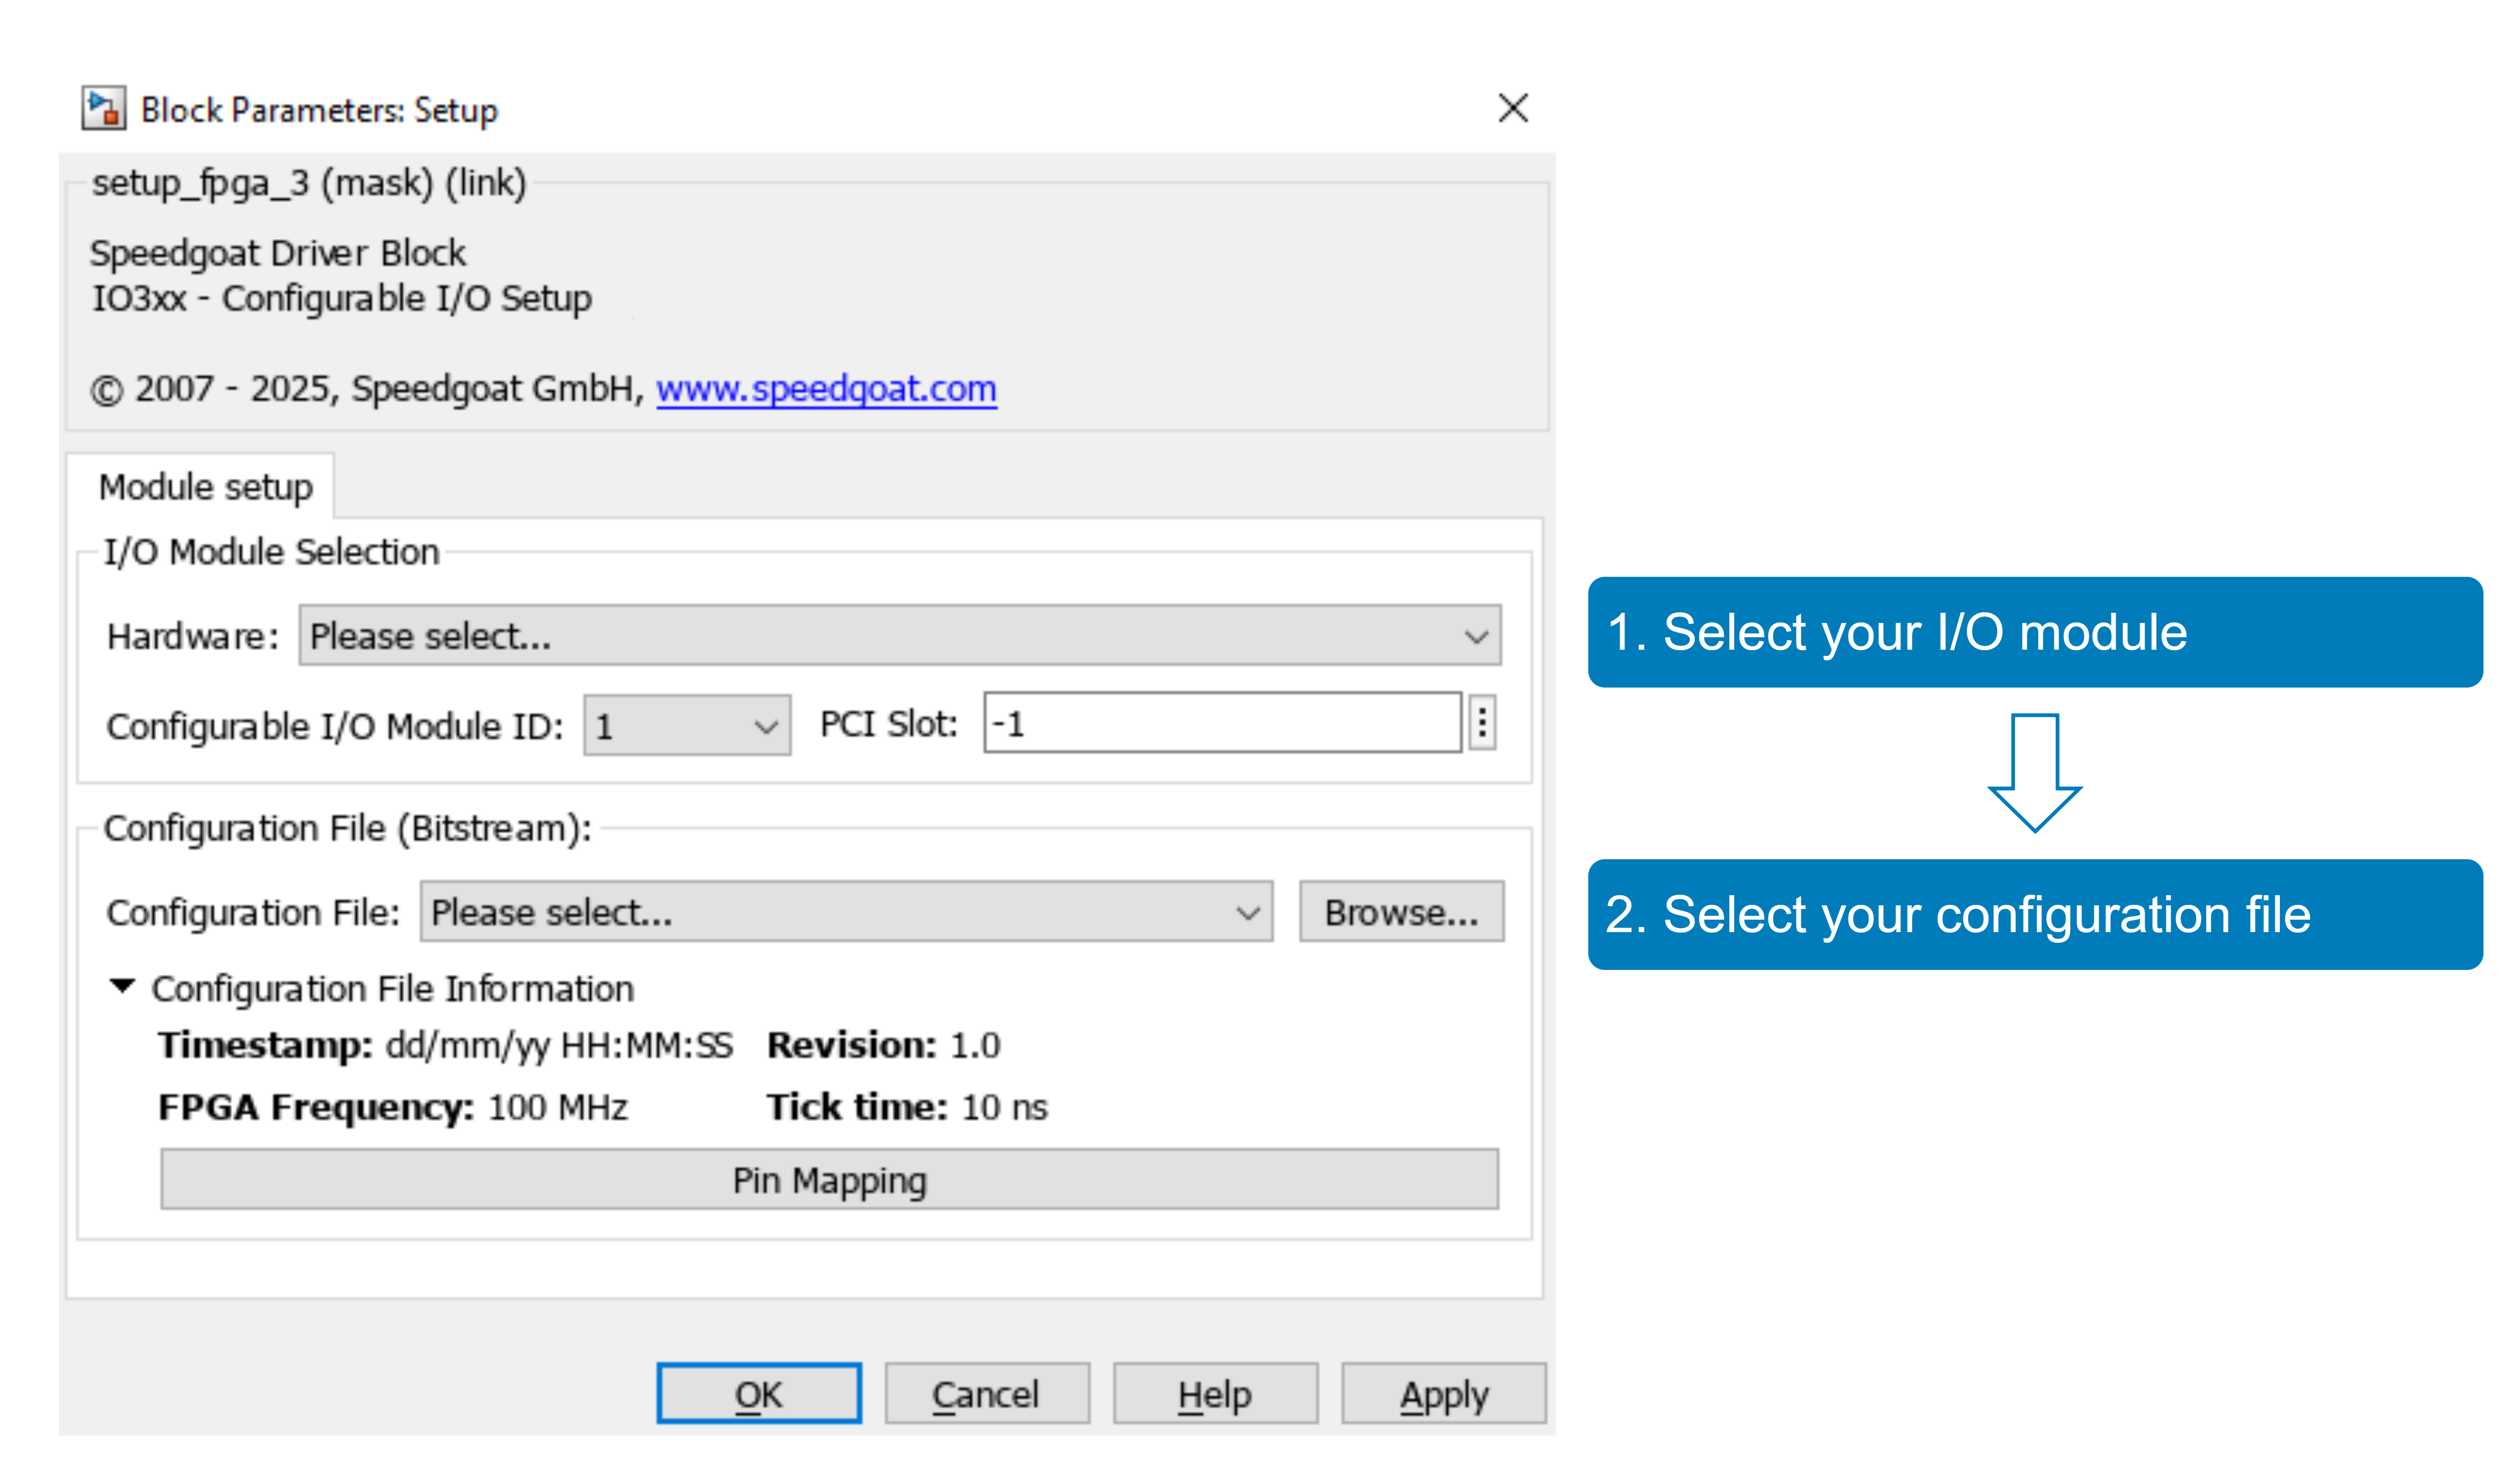

After setting up the I/O module, double click the Speedgoat Interrupt Setup block. Tick the check box "Use as model trigger" and push the "Select Interrupt" button just above. In the newly opened window select the interrupt in the drop down.

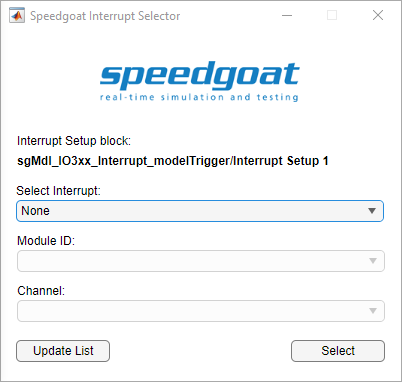

### Model Description

The model will be triggered by the internally generated interrupt on the IO3xx I/O module. By default the frequency is set to 1kHz and can be changed in the Speedgoat IO3xx CoS Interrupt v2 block.

The free-running counter will increment on each model step and log its value to the scope.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);
% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  
% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the interrupt is working as expected, open the Simulink scope that is connected to the interrupt counter. The scope must display the counter value:

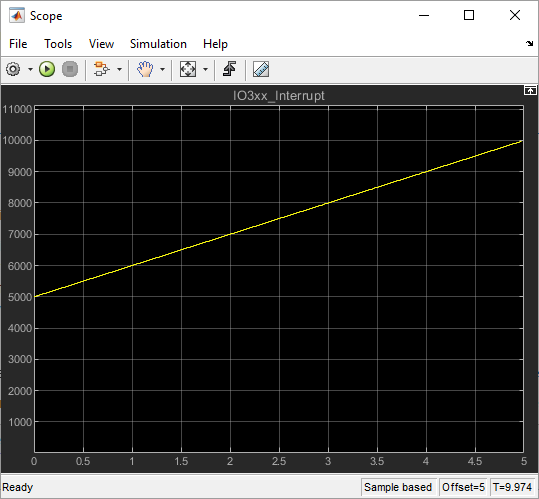

## Additional References

- [Interrupt documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt)